%% DFT Review for MIMO-OFDM Project
% Run each section with Ctrl+Enter to build intuition
% This covers: DFT/IDFT, frequency axis, circular vs linear convolution,
% orthogonality, CP effect, and channel frequency response

 
clear; close all; clc;

%% 1. Basic DFT/IDFT — verify they are inverses
N = 64;
x = randn(1,N) + 1j*randn(1,N);  % random complex signal

 
X = fft(x);       % time -> frequency
x_recovered = ifft(X);  % frequency -> time
fprintf('Section 1: DFT/IDFT roundtrip error = %.2e\n', norm(x - x_recovered));

Section 1: DFT/IDFT roundtrip error = 2.65e-15


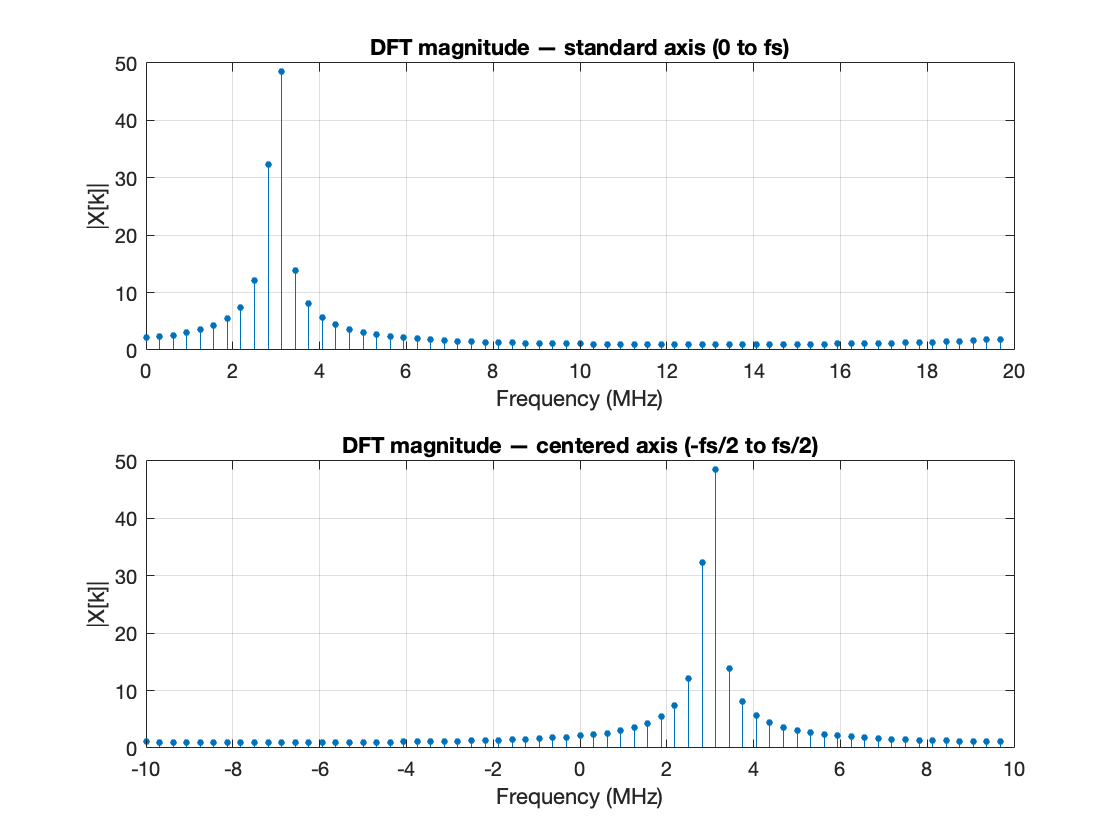

%% 2. What each DFT bin means — frequency axis construction
fs = 20e6;         % sampling rate = 20 MHz
Ts = 1/fs;         % sample spacing
N = 64;
 
% Generate a tone at 3 MHz
f_tone = 3e6;
n = 0:N-1;
x = exp(1j*2*pi*f_tone*n*Ts);
 
X = fft(x);
 
% Frequency axis (0 to fs)
f_axis = (0:N-1) * fs/N;
 
% Centered frequency axis (-fs/2 to fs/2)
f_centered = (-N/2:N/2-1) * fs/N;
 
figure;
subplot(2,1,1);
stem(f_axis/1e6, abs(X), 'filled', 'MarkerSize', 3);
xlabel('Frequency (MHz)'); ylabel('|X[k]|');
title('DFT magnitude — standard axis (0 to fs)');
grid on;
 
subplot(2,1,2);
stem(f_centered/1e6, abs(fftshift(X)), 'filled', 'MarkerSize', 3);
xlabel('Frequency (MHz)'); ylabel('|X[k]|');
title('DFT magnitude — centered axis (-fs/2 to fs/2)');
grid on;

 
fprintf('Section 2: Tone at %.1f MHz appears at bin %d (= %.1f MHz)\n', ...
    f_tone/1e6, round(f_tone/fs*N), round(f_tone/fs*N)*fs/N/1e6);

Section 2: Tone at 3.0 MHz appears at bin 10 (= 3.1 MHz)


%% 3. Orthogonality of DFT basis vectors
N = 16;
k1 = 3;  % subcarrier index 1
k2 = 7;  % subcarrier index 2

 
n = 0:N-1;
e1 = exp(1j*2*pi*k1*n/N);  % basis vector for subcarrier k1
e2 = exp(1j*2*pi*k2*n/N);  % basis vector for subcarrier k2
 
inner_product_same = (1/N) * sum(e1 .* conj(e1));    % should be 1
inner_product_diff = (1/N) * sum(e1 .* conj(e2));    % should be 0
 
fprintf('Section 3: <e_%d, e_%d> = %.6f (should be 1)\n', k1, k1, inner_product_same);

Section 3: <e_3, e_3> = 1.000000 (should be 1)


fprintf('Section 3: <e_%d, e_%d> = %.6f (should be 0)\n', k1, k2, abs(inner_product_diff));

Section 3: <e_3, e_7> = 0.000000 (should be 0)


 
% What happens with non-integer frequency (like CFO)
k_bad = 3.1;  % non-integer — breaks orthogonality
e_bad = exp(1j*2*pi*k_bad*n/N);
inner_product_bad = (1/N) * sum(e_bad .* conj(e1));
 
fprintf('Section 3: <e_%.1f, e_%d> = %.6f (non-zero! orthogonality broken)\n', ...
    k_bad, k1, abs(inner_product_bad));

Section 3: <e_3.1, e_3> = 0.983695 (non-zero! orthogonality broken)


%% 4. Linear convolution vs Circular convolution
N = 8;
x = [1 2 3 4 0 0 0 0];   % length 4 signal, zero-padded to 8
h = [0.5 0.3 0.2 0 0 0 0 0]; % length 3 channel, zero-padded to 8
 
% Linear convolution (what the channel actually does)
y_linear = conv(x(1:4), h(1:3));
 
% Circular convolution via DFT (what OFDM math assumes)
Y_circ = fft(x) .* fft(h);
y_circ = ifft(Y_circ);
 
% With zero-padding to length >= len(x)+len(h)-1, they match
fprintf('\nSection 4: Linear vs Circular convolution\n');


Section 4: Linear vs Circular convolution


fprintf('Linear conv result:   '); fprintf('%.2f ', y_linear); fprintf('\n');

Linear conv result:   0.50 1.30 2.30 3.30 1.80 0.80 


fprintf('Circular conv (N=8):  '); fprintf('%.2f ', real(y_circ)); fprintf('\n');

Circular conv (N=8):  0.50 1.30 2.30 3.30 1.80 0.80 0.00 0.00 


fprintf('They match: %s\n', mat2str(norm(y_linear - y_circ(1:length(y_linear))) < 1e-10));

They match: true


%% 5. CP makes linear convolution look circular — THE key OFDM insight
N = 8;          % OFDM symbol length
L = 3;          % channel length
Ncp = L - 1;    % CP length = channel length - 1
 
% OFDM symbol (IFFT of random QAM data)
X_data = (2*randi([0,1],1,N)-1) + 1j*(2*randi([0,1],1,N)-1); % QPSK
x_ofdm = ifft(X_data);
 
% Channel
h = [0.8 0.4+0.2j 0.1-0.1j];
 
% --- Without CP ---
y_no_cp = conv(x_ofdm, h);
y_no_cp = y_no_cp(1:N);  % take first N samples
 
Y_no_cp = fft(y_no_cp);
H_freq = fft(h, N);
 
% Check if Y = H.*X holds
error_no_cp = norm(Y_no_cp - H_freq .* X_data);
 
% --- With CP ---
x_with_cp = [x_ofdm(end-Ncp+1:end), x_ofdm];  % add CP
y_with_cp = conv(x_with_cp, h);
y_after_cp_removal = y_with_cp(Ncp+1 : Ncp+N);  % remove CP
 
Y_with_cp = fft(y_after_cp_removal);
 
% Check if Y = H.*X holds
error_with_cp = norm(Y_with_cp - H_freq .* X_data);
 
fprintf('\nSection 5: CP effect on Y[k] = H[k]*X[k]\n');


Section 5: CP effect on Y[k] = H[k]*X[k]


fprintf('Error WITHOUT CP: %.4f (bad — linear conv ≠ multiplication)\n', error_no_cp);

Error WITHOUT CP: 1.1126 (bad — linear conv ≠ multiplication)


fprintf('Error WITH CP:    %.2e (good — circular conv = multiplication)\n', error_with_cp);

Error WITH CP:    7.49e-16 (good — circular conv = multiplication)


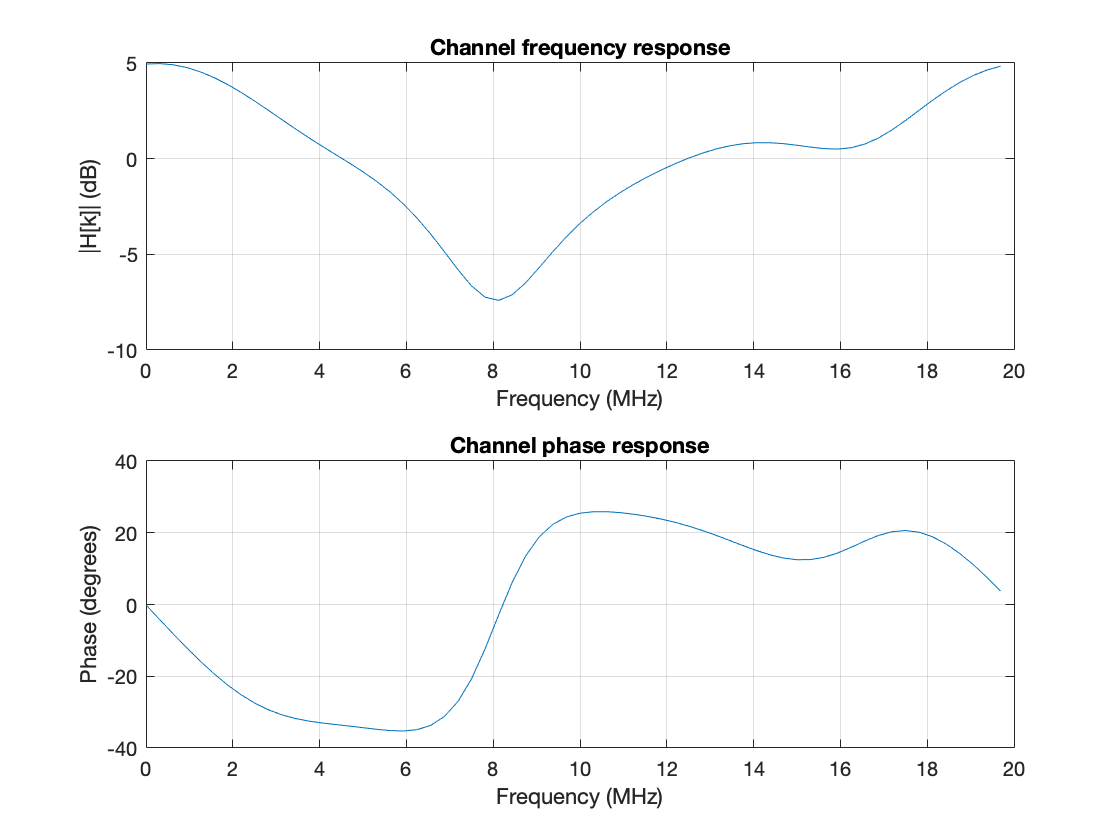

%% 6. Channel frequency response from tap coefficients
% This is what you do in the project: generate H[k] from h[n]
 
N = 64;
h = [1, 0.5*exp(-1j*0.3), 0.2*exp(1j*0.8), 0.1, 0.05]; % 5-tap channel
L = length(h);
 
% Frequency response = FFT of taps, zero-padded to N
H = fft(h, N);
 
figure;
subplot(2,1,1);
plot((0:N-1)*fs/N/1e6, 20*log10(abs(H)));
xlabel('Frequency (MHz)'); ylabel('|H[k]| (dB)');
title('Channel frequency response');
grid on;
 
subplot(2,1,2);
plot((0:N-1)*fs/N/1e6, angle(H)*180/pi);
xlabel('Frequency (MHz)'); ylabel('Phase (degrees)');
title('Channel phase response');
grid on;

 
fprintf('\nSection 6: Channel has %d taps, frequency response at %d subcarriers\n', L, N);


Section 6: Channel has 5 taps, frequency response at 64 subcarriers


fprintf('This is the H[k] that multiplies each OFDM subcarrier\n');

This is the H[k] that multiplies each OFDM subcarrier


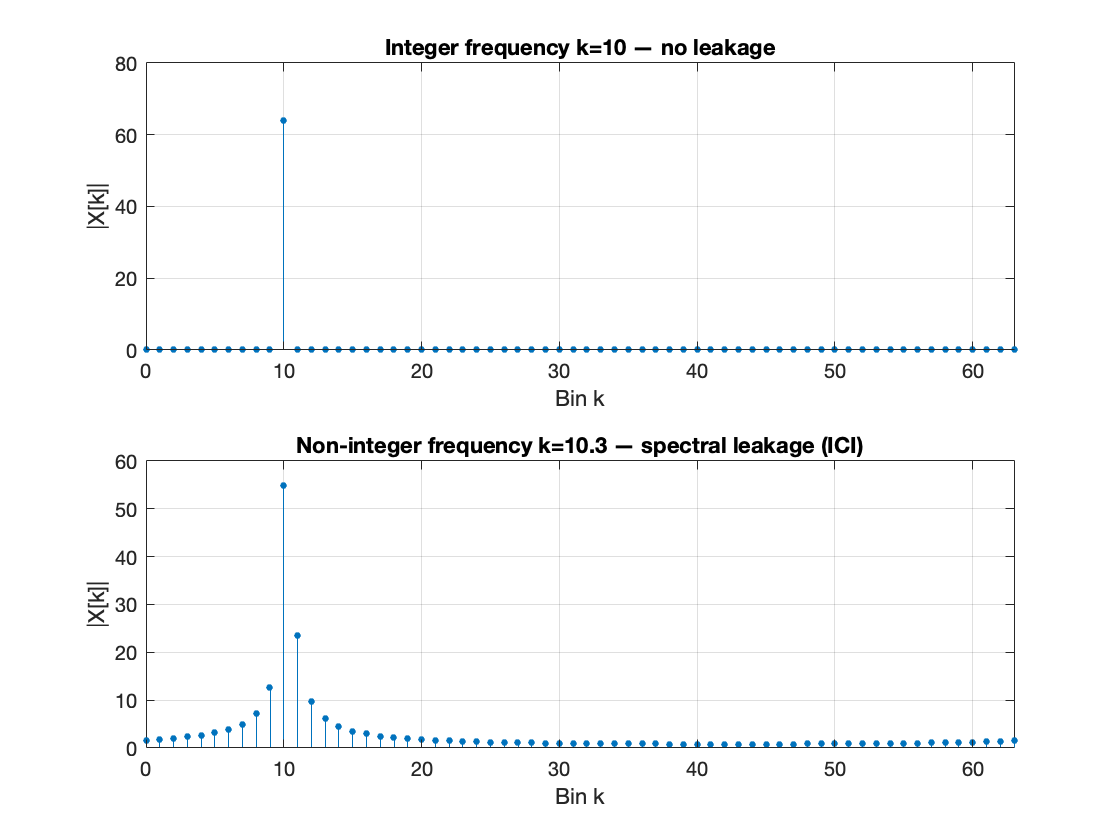

 
%% 6b. Windowing and Spectral Leakage
N = 64;
n = 0:N-1;
 
% Signal at exactly bin 10 (integer frequency — no leakage)
k_exact = 10;
x_exact = exp(1j*2*pi*k_exact*n/N);
X_exact = fft(x_exact);
 
% Signal between bins (non-integer — leakage, like CFO)
k_between = 10.3;
x_between = exp(1j*2*pi*k_between*n/N);
X_between = fft(x_between);
 
figure;
subplot(2,1,1);
stem(0:N-1, abs(X_exact), 'filled', 'MarkerSize', 3);
xlabel('Bin k'); ylabel('|X[k]|');
title(sprintf('Integer frequency k=%d — no leakage', k_exact));
grid on; xlim([0 N-1]);
 
subplot(2,1,2);
stem(0:N-1, abs(X_between), 'filled', 'MarkerSize', 3);
xlabel('Bin k'); ylabel('|X[k]|');
title(sprintf('Non-integer frequency k=%.1f — spectral leakage (ICI)', k_between));
grid on; xlim([0 N-1]);

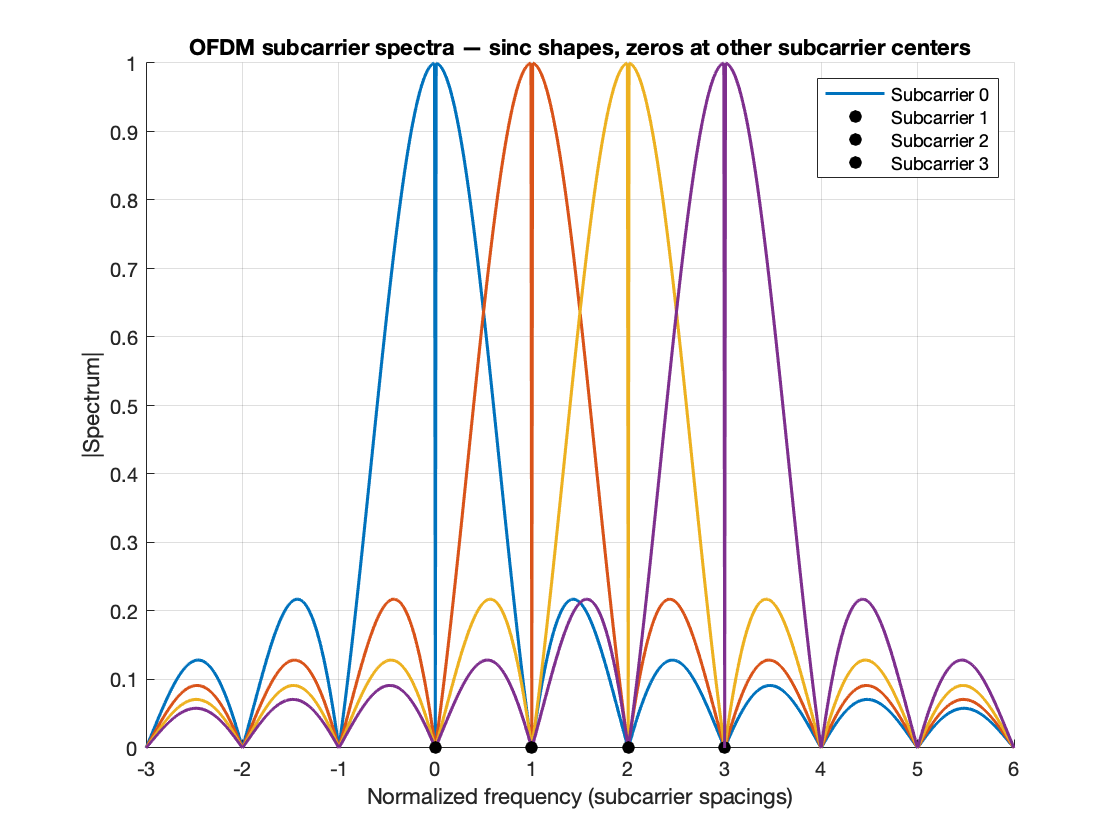

 
% OFDM subcarrier spectra — sinc shapes overlapping
figure;
f_fine = linspace(-3, 6, 1000);
colors = lines(4);
hold on;
for k = 0:3
    sinc_spectrum = sin(pi*(f_fine - k)) ./ (pi*(f_fine - k) + eps);
    plot(f_fine, abs(sinc_spectrum), 'Color', colors(k+1,:), 'LineWidth', 1.5);
    % Mark the zero crossings at other subcarrier centers
    for m = 0:3
        if m ~= k
            plot(m, 0, 'ko', 'MarkerSize', 6, 'MarkerFaceColor', 'k');
        end
    end
end
xlabel('Normalized frequency (subcarrier spacings)');
ylabel('|Spectrum|');
title('OFDM subcarrier spectra — sinc shapes, zeros at other subcarrier centers');
legend('Subcarrier 0', 'Subcarrier 1', 'Subcarrier 2', 'Subcarrier 3');
grid on;

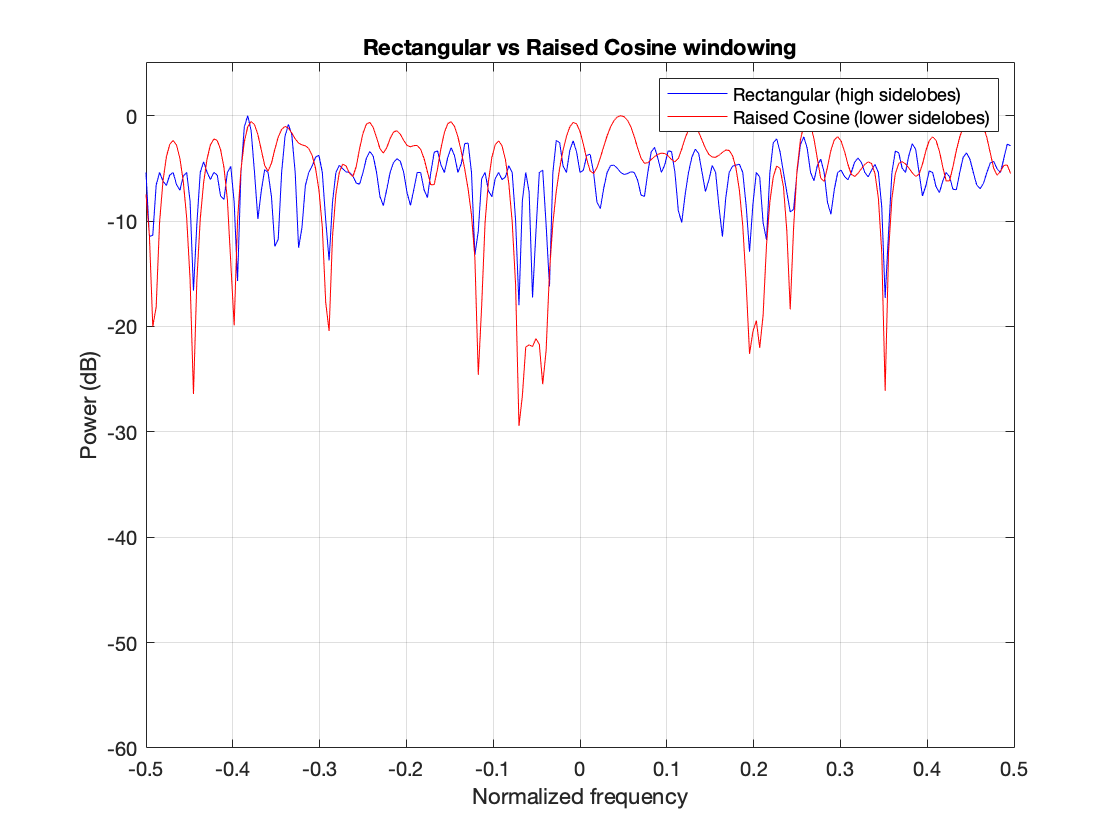

 
% Raised cosine windowing effect on spectrum
x_ofdm = ifft((2*randi([0,1],1,N)-1) + 1j*(2*randi([0,1],1,N)-1));
 
% Rectangular window (default)
X_rect = fftshift(fft(x_ofdm, 4*N));
 
% Raised cosine window
beta = 8; % roll-off samples
w_rc = ones(1,N);
w_rc(1:beta) = 0.5*(1 - cos(pi*(0:beta-1)/beta));
w_rc(N-beta+1:N) = 0.5*(1 + cos(pi*(0:beta-1)/beta));
X_rc = fftshift(fft(x_ofdm .* w_rc, 4*N));
 
f_axis_fine = (-2*N:2*N-1) / (4*N);
figure;
plot(f_axis_fine, 20*log10(abs(X_rect)/max(abs(X_rect))+eps), 'b-'); hold on;
plot(f_axis_fine, 20*log10(abs(X_rc)/max(abs(X_rc))+eps), 'r-');
xlabel('Normalized frequency'); ylabel('Power (dB)');
title('Rectangular vs Raised Cosine windowing');
legend('Rectangular (high sidelobes)', 'Raised Cosine (lower sidelobes)');
ylim([-60 5]); grid on;

 
fprintf('\nSection 6b: Windowing\n');


Section 6b: Windowing


fprintf('Integer frequency: all energy in one bin (orthogonal)\n');

Integer frequency: all energy in one bin (orthogonal)


fprintf('Non-integer frequency: energy leaks to all bins (ICI)\n');

Non-integer frequency: energy leaks to all bins (ICI)


fprintf('Raised cosine window reduces out-of-band power at cost of main lobe width\n');

Raised cosine window reduces out-of-band power at cost of main lobe width
